% Date created: 221216

% This script takes SPT data from HaloTag-PBP2B and makes violin DABEST
% plots of lifetimes across various conditions.

## User parameters

speedcut = [0 4]; % [nm/s]
interval = 1; % [s] acquisition interval

## Load data

datadir = '\\campus\rdw\FMS CBCB\nsh167\Shared\data\Whitley-Kevin\Data_Analyzed\PBP2B_results\';

cdm30_file = '221128_sh147_cdm_30c_vercini_kymo_unreg_clean_polyline.mat';
cdm37_file = '221207_sh147_cdm_37c_vercini_kymo_unreg_clean_polyline.mat';
phmm30_file = '221111_sh147_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';
phmm37_file = '221122_sh147_phmm_37c_vercini_kymo_unreg_clean_polyline.mat';

pc19_file = '221115_sh147_phmm_30c_pc19_vercini_kymo_unreg_clean_polyline.mat';
penG_file = '221116_sh147_phmm_30c_penG_vercini_kymo_unreg_clean_polyline.mat';
fos_file = '221116_sh147_phmm_30c_fosfomycin_vercini_kymo_unreg_clean_polyline.mat';
g106s_file = '221208_sh147sh056_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';

load([datadir cdm30_file])
load([datadir cdm37_file])
load([datadir phmm30_file])
load([datadir phmm37_file])

load([datadir pc19_file])
load([datadir penG_file])
load([datadir fos_file])
load([datadir g106s_file])

## Get lifetimes

% ALL SINGLE SEGMENT LIFETIMES

cdm30_seg_lifetime = abs(cdm30_life.Time_s_(abs(cdm30_life.Speed_nm_s_)>speedcut(1) & abs(cdm30_life.Speed_nm_s_)<speedcut(2) & cdm30_life.Segment_~=0));
cdm37_seg_lifetime = abs(cdm37_life.Time_s_(abs(cdm37_life.Speed_nm_s_)>speedcut(1) & abs(cdm37_life.Speed_nm_s_)<speedcut(2) & cdm37_life.Segment_~=0));
phmm30_seg_lifetime = abs(phmm30_life.Time_s_(abs(phmm30_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_life.Speed_nm_s_)<speedcut(2) & phmm30_life.Segment_~=0));
phmm37_seg_lifetime = abs(phmm37_life.Time_s_(abs(phmm37_life.Speed_nm_s_)>speedcut(1) & abs(phmm37_life.Speed_nm_s_)<speedcut(2) & phmm37_life.Segment_~=0));

pc19_seg_lifetime = abs(phmm30_pc19_life.Time_s_(abs(phmm30_pc19_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_pc19_life.Speed_nm_s_)<speedcut(2) & phmm30_pc19_life.Segment_~=0));
penG_seg_lifetime = abs(phmm30_penG_life.Time_s_(abs(phmm30_penG_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_penG_life.Speed_nm_s_)<speedcut(2) & phmm30_penG_life.Segment_~=0));
fos_seg_lifetime = abs(phmm30_fos_life.Time_s_(abs(phmm30_fos_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_fos_life.Speed_nm_s_)<speedcut(2) & phmm30_fos_life.Segment_~=0));
g106s_seg_lifetime = abs(phmm30_g106s_life.Time_s_(abs(phmm30_g106s_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_g106s_life.Speed_nm_s_)<speedcut(2) & phmm30_g106s_life.Segment_~=0));

% ONLY MIDDLE SEGMENT LIFETIMES

cdm30_middle_seg = getKymotraceMiddleSegments(cdm30_life, interval);
cdm37_middle_seg = getKymotraceMiddleSegments(cdm37_life, interval);
phmm30_middle_seg = getKymotraceMiddleSegments(phmm30_life, interval);
phmm37_middle_seg = getKymotraceMiddleSegments(phmm37_life, interval);

pc19_middle_seg = getKymotraceMiddleSegments(phmm30_pc19_life, interval);
penG_middle_seg = getKymotraceMiddleSegments(phmm30_penG_life, interval);
fos_middle_seg = getKymotraceMiddleSegments(phmm30_fos_life, interval);
g106s_middle_seg = getKymotraceMiddleSegments(phmm30_g106s_life, interval);

cdm30_mid_seg_lifetime = abs(cdm30_middle_seg.Time_s_(abs(cdm30_middle_seg.Speed_nm_s_)>speedcut(1) & abs(cdm30_middle_seg.Speed_nm_s_)<speedcut(2) & cdm30_middle_seg.Segment_~=0));
cdm37_mid_seg_lifetime = abs(cdm37_middle_seg.Time_s_(abs(cdm37_middle_seg.Speed_nm_s_)>speedcut(1) & abs(cdm37_middle_seg.Speed_nm_s_)<speedcut(2) & cdm37_middle_seg.Segment_~=0));
phmm30_mid_seg_lifetime = abs(phmm30_middle_seg.Time_s_(abs(phmm30_middle_seg.Speed_nm_s_)>speedcut(1) & abs(phmm30_middle_seg.Speed_nm_s_)<speedcut(2) & phmm30_middle_seg.Segment_~=0));
phmm37_mid_seg_lifetime = abs(phmm37_middle_seg.Time_s_(abs(phmm37_middle_seg.Speed_nm_s_)>speedcut(1) & abs(phmm37_middle_seg.Speed_nm_s_)<speedcut(2) & phmm37_middle_seg.Segment_~=0));

pc19_mid_seg_lifetime = abs(pc19_middle_seg.Time_s_(abs(pc19_middle_seg.Speed_nm_s_)>speedcut(1) & abs(pc19_middle_seg.Speed_nm_s_)<speedcut(2) & pc19_middle_seg.Segment_~=0));
penG_mid_seg_lifetime = abs(penG_middle_seg.Time_s_(abs(penG_middle_seg.Speed_nm_s_)>speedcut(1) & abs(penG_middle_seg.Speed_nm_s_)<speedcut(2) & penG_middle_seg.Segment_~=0));
fos_mid_seg_lifetime = abs(fos_middle_seg.Time_s_(abs(fos_middle_seg.Speed_nm_s_)>speedcut(1) & abs(fos_middle_seg.Speed_nm_s_)<speedcut(2) & fos_middle_seg.Segment_~=0));
g106s_mid_seg_lifetime = abs(g106s_middle_seg.Time_s_(abs(g106s_middle_seg.Speed_nm_s_)>speedcut(1) & abs(g106s_middle_seg.Speed_nm_s_)<speedcut(2) & g106s_middle_seg.Segment_~=0));

% LIFETIMES OF FULL TRACKS

cdm30_full_lifetime = abs(cdm30_life.Time_s_(abs(cdm30_life.Speed_nm_s_)>speedcut(1) & abs(cdm30_life.Speed_nm_s_)<speedcut(2) & cdm30_life.Segment_==0));
cdm37_full_lifetime = abs(cdm37_life.Time_s_(abs(cdm37_life.Speed_nm_s_)>speedcut(1) & abs(cdm37_life.Speed_nm_s_)<speedcut(2) & cdm37_life.Segment_==0));
phmm30_full_lifetime = abs(phmm30_life.Time_s_(abs(phmm30_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_life.Speed_nm_s_)<speedcut(2) & phmm30_life.Segment_==0));
phmm37_full_lifetime = abs(phmm37_life.Time_s_(abs(phmm37_life.Speed_nm_s_)>speedcut(1) & abs(phmm37_life.Speed_nm_s_)<speedcut(2) & phmm37_life.Segment_==0));

pc19_full_lifetime = abs(phmm30_pc19_life.Time_s_(abs(phmm30_pc19_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_pc19_life.Speed_nm_s_)<speedcut(2) & phmm30_pc19_life.Segment_==0));
penG_full_lifetime = abs(phmm30_penG_life.Time_s_(abs(phmm30_penG_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_penG_life.Speed_nm_s_)<speedcut(2) & phmm30_penG_life.Segment_==0));
fos_full_lifetime = abs(phmm30_fos_life.Time_s_(abs(phmm30_fos_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_fos_life.Speed_nm_s_)<speedcut(2) & phmm30_fos_life.Segment_==0));
g106s_full_lifetime = abs(phmm30_g106s_life.Time_s_(abs(phmm30_g106s_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_g106s_life.Speed_nm_s_)<speedcut(2) & phmm30_g106s_life.Segment_==0));

## Prepare for plotting

% ALL SINGLE SEGMENT LIFETIMES

c_cdm30_seg_lifetime = repmat({'cdm30'}, length(cdm30_seg_lifetime), 1);
c_cdm37_seg_lifetime = repmat({'cdm37'}, length(cdm37_seg_lifetime), 1);
c_phmm30_seg_lifetime = repmat({'phmm30'}, length(phmm30_seg_lifetime), 1);
c_phmm37_seg_lifetime = repmat({'phmm37'}, length(phmm37_seg_lifetime), 1);

c_pc19_seg_lifetime = repmat({'pc19'}, length(pc19_seg_lifetime), 1);
c_penG_seg_lifetime = repmat({'penG'}, length(penG_seg_lifetime), 1);
c_fos_seg_lifetime = repmat({'fos'}, length(fos_seg_lifetime), 1);
c_g106s_seg_lifetime = repmat({'g106s'}, length(g106s_seg_lifetime), 1);

% ONLY MIDDLE SEGMENT LIFETIMES

c_cdm30_mid_seg_lifetime = repmat({'cdm30'}, length(cdm30_mid_seg_lifetime), 1);
c_cdm37_mid_seg_lifetime = repmat({'cdm37'}, length(cdm37_mid_seg_lifetime), 1);
c_phmm30_mid_seg_lifetime = repmat({'phmm30'}, length(phmm30_mid_seg_lifetime), 1);
c_phmm37_mid_seg_lifetime = repmat({'phmm37'}, length(phmm37_mid_seg_lifetime), 1);

c_pc19_mid_seg_lifetime = repmat({'pc19'}, length(pc19_mid_seg_lifetime), 1);
c_penG_mid_seg_lifetime = repmat({'penG'}, length(penG_mid_seg_lifetime), 1);
c_fos_mid_seg_lifetime = repmat({'fos'}, length(fos_mid_seg_lifetime), 1);
c_g106s_mid_seg_lifetime = repmat({'g106s'}, length(g106s_mid_seg_lifetime), 1);

% FULL TRACK LIFETIMES

c_cdm30_full_lifetime = repmat({'cdm30'}, length(cdm30_full_lifetime), 1);
c_cdm37_full_lifetime = repmat({'cdm37'}, length(cdm37_full_lifetime), 1);
c_phmm30_full_lifetime = repmat({'phmm30'}, length(phmm30_full_lifetime), 1);
c_phmm37_full_lifetime = repmat({'phmm37'}, length(phmm37_full_lifetime), 1);

c_pc19_full_lifetime = repmat({'pc19'}, length(pc19_full_lifetime), 1);
c_penG_full_lifetime = repmat({'penG'}, length(penG_full_lifetime), 1);
c_fos_full_lifetime = repmat({'fos'}, length(fos_full_lifetime), 1);
c_g106s_full_lifetime = repmat({'g106s'}, length(g106s_full_lifetime), 1);

## Plot

delta_name_plot = 1×1 cell array
    {' '}


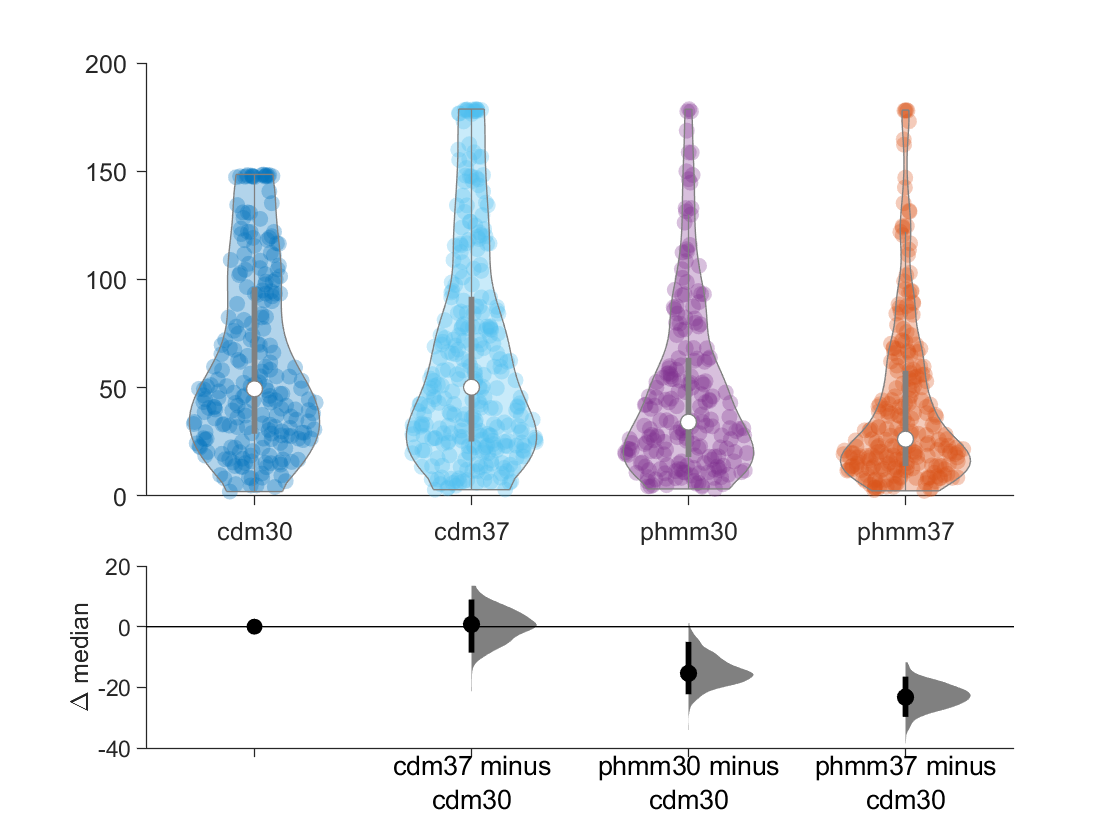

ans = 7×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'cdm30'             }       49.5      44.25       56.5    235
    {'cdm37'             }      50.25       42.5         58    303
    {'phmm30'            }     34.125     29.333     43.125    206
    {'phmm37'            }      26.25       22.5      31.75    251
    {'cdm37 minus cdm30' }       0.75    -9.8333      10.25    NaN
    {'phmm30 minus cdm30'}    -15.375    -23.583    -4.0833    NaN
    {'phmm37 minus cdm30'}     -23.25    -31.625    -15.375    NaN


% ALL SINGLE SEGMENT LIFETIMES

violinplusdabest([cdm30_seg_lifetime; cdm37_seg_lifetime; phmm30_seg_lifetime; phmm37_seg_lifetime], [c_cdm30_seg_lifetime; c_cdm37_seg_lifetime; c_phmm30_seg_lifetime; c_phmm37_seg_lifetime],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})

delta_name_plot = 1×1 cell array
    {' '}


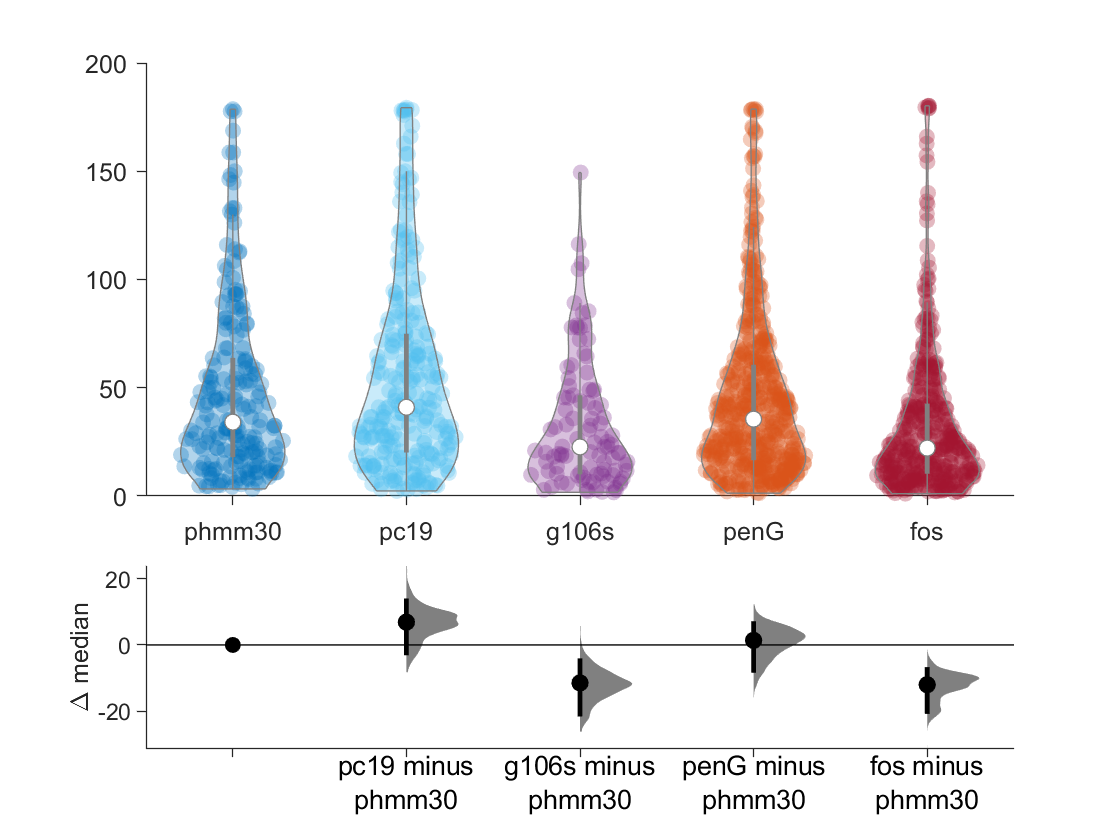

ans = 9×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'phmm30'            }     34.125     29.167     43.125    206
    {'pc19'              }         41         36      47.75    263
    {'g106s'             }     22.667       18.5      30.75     99
    {'penG'              }       35.5     29.917     40.167    498
    {'fos'               }     22.125     19.692     24.833    381
    {'pc19 minus phmm30' }      6.875    -4.4375         16    NaN
    {'g106s minus phmm30'}    -11.458    -22.625    -3.0625    NaN
    {'penG minus phmm30' }      1.375    -10.021     8.0417    NaN
    {'fos minus phmm30'  }        -12    -21.625    -5.5833    NaN



violinplusdabest([phmm30_seg_lifetime; pc19_seg_lifetime; g106s_seg_lifetime; penG_seg_lifetime; fos_seg_lifetime], [c_phmm30_seg_lifetime; c_pc19_seg_lifetime; c_g106s_seg_lifetime; c_penG_seg_lifetime; c_fos_seg_lifetime],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})

delta_name_plot = 1×1 cell array
    {' '}


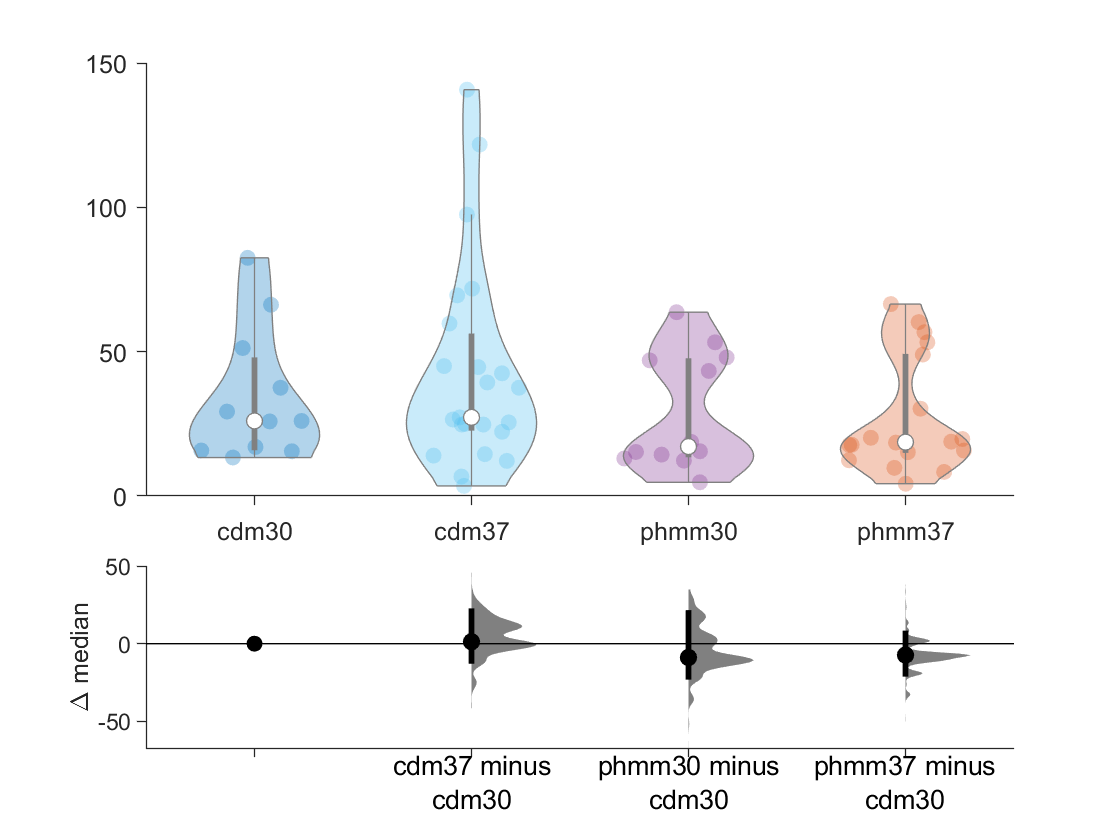

ans = 7×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'cdm30'             }         26      15.75      51.25     11
    {'cdm37'             }      27.25      24.75         45     23
    {'phmm30'            }     17.125     13.667       47.5     12
    {'phmm37'            }     18.667     15.458     34.583     18
    {'cdm37 minus cdm30' }       1.25        -24       25.5    NaN
    {'phmm30 minus cdm30'}     -8.875     -35.75     26.333    NaN
    {'phmm37 minus cdm30'}    -7.3333    -32.417     13.625    NaN



% ONLY MIDDLE SEGMENT LIFETIMES

violinplusdabest([cdm30_mid_seg_lifetime; cdm37_mid_seg_lifetime; phmm30_mid_seg_lifetime; phmm37_mid_seg_lifetime], [c_cdm30_mid_seg_lifetime; c_cdm37_mid_seg_lifetime; c_phmm30_mid_seg_lifetime; c_phmm37_mid_seg_lifetime],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})


violinplusdabest([phmm30_mid_seg_lifetime; pc19_mid_seg_lifetime; g106s_mid_seg_lifetime; penG_mid_seg_lifetime; fos_mid_seg_lifetime], [c_phmm30_mid_seg_lifetime; c_pc19_mid_seg_lifetime; c_g106s_mid_seg_lifetime; c_penG_mid_seg_lifetime; c_fos_mid_seg_lifetime],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})

Error using bootstrp>bootEvalCommand (line 302)
BOOTFUN must have at least one non-scalar argument.

Error in bootstrp (line 145)
[n,booteval] = bootEvalCommand(bootfun,bootargs{:});

Error in bootci>bootbca (<a href="ma


% FULL TRACK LIFETIMES

violinplusdabest([cdm30_full_lifetime; cdm37_full_lifetime; phmm30_full_lifetime; phmm37_full_lifetime], [c_cdm30_full_lifetime; c_cdm37_full_lifetime; c_phmm30_full_lifetime; c_phmm37_full_lifetime],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})

violinplusdabest([phmm30_full_lifetime; pc19_full_lifetime; g106s_full_lifetime; penG_full_lifetime; fos_full_lifetime], [c_phmm30_full_lifetime; c_pc19_full_lifetime; c_g106s_full_lifetime; c_penG_full_lifetime; c_fos_full_lifetime],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})